# Solving 2nd Order ODEs - Machine Problem 6

In your final machine problem for the semester, you are going to solve a 2nd order ODE using the 4th order Runge-Kutta Method. Choose one of the problems to solve from the document "P131 MP 06 Problems.docx."

clear; clc; clf;

## Bouncing Ball (15 pts.)

Write down below, in Text format, the equation of motion for a falling object.  


$$\frac{d^2 y}{dt^2 }=-g$$


Break down this second order ODE into two first order ODEs. Show your complete solution in Text format.

Let $v=\frac{\textrm{dy}}{\textrm{dt}}$. The second order ODE above then becomes $\frac{\textrm{dv}}{\textrm{dt}}=-g$. These constitute our two first order ODEs.

In order to determine the height, $y$, and the velocity, $v$, you need to solve for the solutions to these two 1st Order ODEs simultaneously. Solve for the height and velocity of a bouncing ball as a function of time, with a coefficient of restitution of 0.95. Choose the range of time such that its trajectory shows ten bounces. 

Define the step size and length of time. You may change the end value later in order to display ten bounces.

h = 0.01;       % step size
t = 0:h:75;     % time scale from 0 to 75 seconds

Choose an appropriate initial height and velocity and type them down in the field below. Comment the units you are using. 

y = zeros(1,length(t));
v = zeros(1,length(t));
v(1) = 10;      % initial velocity of 10 meters per second
y(1) = 100;     % initial height of 100 meters with respect to the ground

Write down the correct code below in order to simultaneously solve for the velocity and height of the ball. 

for i = 2:length(t)
    k1v = -9.8;     % this is the right hand side
    k2v = -9.8;     % of the differential equation 
    k3v = -9.8;     % for velocity
    k4v = -9.8;     
 
    if y(i-1) <= 0          % this code states that if the height is less than
        v(i) = -0.95*v(i-1);% zero, then the next value of the velocity of the 
                            % ball should have a reduced magnitude reduced by 95%
                            % and opposite direction
                            
    else                    % otherwise  
        
        v(i) = v(i-1) + (1/6)*(k1v+2*k2v+2*k3v+k4v)*h;      
                            % the next value is computed using RK4 method
    end                           
    
    k1y = v(i);     % this computes for displacement
    k2y = v(i);     % of the ball using the equation
    k3y = v(i);     % dy/dt = f(t,y) = v
    k4y = v(i);
    y(i) = y(i-1) + (1/6)*(k1y+2*k2y+2*k3y+k4y)*h;
        
end

Plot the height and velocity of the ball. Add appropriate titles to the plot and x- and y-axes labels.

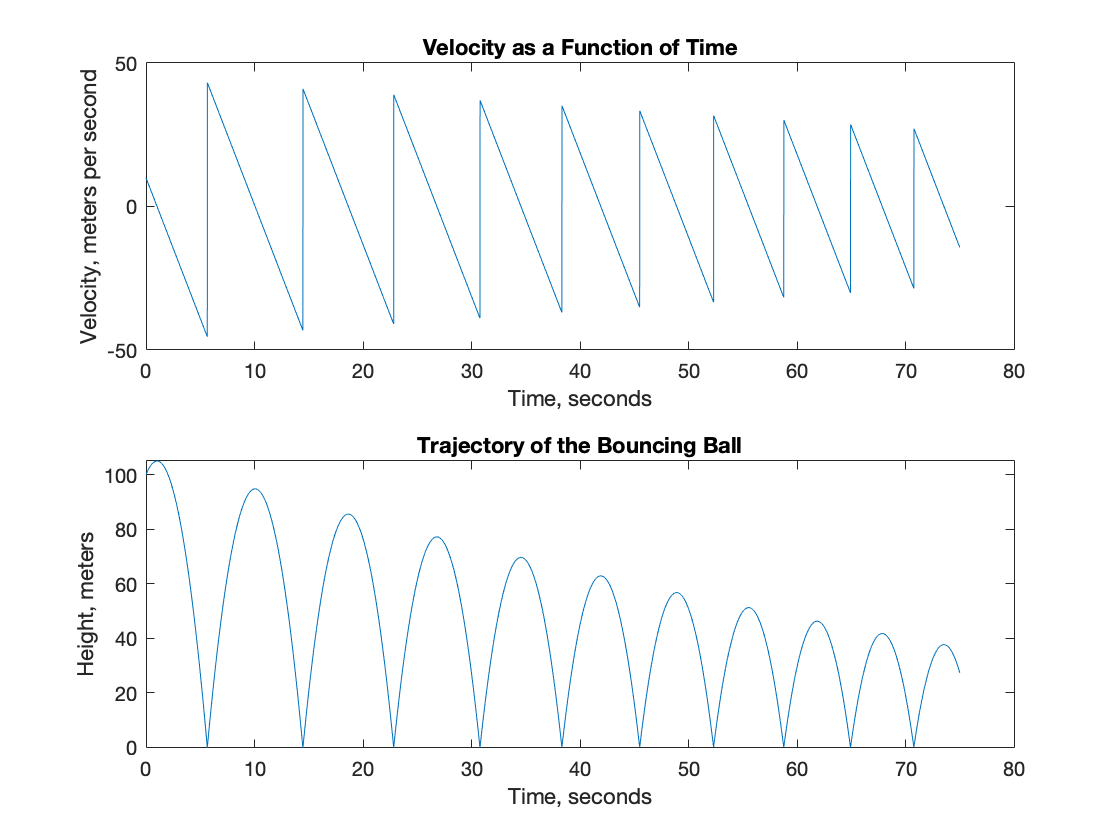

subplot(2,1,1)
plot(t,v);
title('Velocity as a Function of Time');
xlabel('Time, seconds');
ylabel('Velocity, meters per second');
subplot(2,1,2)
plot(t,y);
title('Trajectory of the Bouncing Ball');
xlabel('Time, seconds');
ylabel('Height, meters');

For an additional 5 points, animate the bouncing ball based on the solution of this ODE. Display the instantaneous height and velocity as the ball is bouncing.

*Note: When animating, it may not be necessary to display all points in order to decrease the playing time. You may increase the step size for time.*

figure;
z = zeros(1,length(t));
j = 1;
for i = 1:50:length(t)
    plot(t,y); hold on;
    k = plot(t(i),y(i),'ro','MarkerFaceColor','r'); hold off;
    set(k,'XData',t(i),'YData',y(i),'MarkerSize',12)
    axis([0 75 -10 110]);
    line(t,z)
    pause(0.1)
%     M(j) = getframe;
    j = j + 1;
end
% movie(M,2,15)

## Falling Parachutist (25 pts.)

Write down below, in Text format, the equation of motion for a falling parachutist, with mass, $m=75$$kg$, during the first 15 seconds when the dragging force is proportional to the square of the velocity. Let the dragging force, $k=0.235$$kg/m$. 


$$\frac{d^2 y}{dt^2 }=-\left\lbrack \left(\frac{k}{m}\right)v^2 -g\right\rbrack$$


Break down this second order ODE into two first order ODEs. Show your complete solution in Text format.

Let $v=\frac{\textrm{dy}}{\textrm{dt}}$. The second order ODE above then becomes $\frac{\textrm{dv}}{\textrm{dt}}=-\left\lbrack \left(\frac{k}{m}\right)v^2 -g\right\rbrack$. These constitute our two first order ODEs.

Write down below, in Text format, the equation of motion for a falling parachutist, with mass, $m=75$$kg$, after the first 15 seconds when the drag coefficient is directly proportional to the velocity. Let the drag coefficient, $c=50$$kg/s$. 


$$\frac{d^2 y}{dt^2 }=-\left\lbrack \left(\frac{c}{m}\right)v-g\right\rbrack$$


Break down this second order ODE into two first order ODEs. Show your complete solution in Text format.

Let $v=\frac{\textrm{dy}}{\textrm{dt}}$. The second order ODE above then becomes $\frac{\textrm{dv}}{\textrm{dt}}=-\left\lbrack \left(\frac{c}{m}\right)v-g\right\rbrack$. These constitute our two first order ODEs.

In order to determine the height, $y$, and the velocity, $v$, you need to solve for the solutions to these two sets of 1st Order ODEs simultaneously. Solve for the height, velocity and acceleration, of the parachutist as a function of time from $t=0$ to $t=30$$s$.

Define the step size and length of time. 

h = 0.01;       % step size
t = 0:h:30;     % time scale from 0 to 75 seconds

Choose an appropriate initial height and velocity and type them down in the field below. Comment the units you are using. 

y = zeros(1,length(t));
v = zeros(1,length(t));
a = zeros(1,length(t));
y(1) = 0;      % initial height of 0 meters
v(1) = 0;      % initial velocity of 0 meters per second
a(1) = 9.8;   % initial acceleration of -9.8 meters per second per second

Write down the correct code below in order to simultaneously solve for the acceleration, velocity and height of the ball. 

for i = 2:length(t)
    if t(i) <= 15                       % this code solves for the trajectory
        k1 = f( v(i-1) );               % between the time 0 and 15 seconds
        k2 = f( v(i-1) + 0.5*k1*h );    % just before the chute is opened
        k3 = f( v(i-1) + 0.5*k2*h );
        k4 = f( v(i-1) + k3*h );
    else
        k1 = g( v(i-1) );               % this code solves for the trajectory
        k2 = g( v(i-1) + 0.5*k1*h );    % after the time 15 seconds after the
        k3 = g( v(i-1) + 0.5*k2*h );    % chute is opened
        k4 = g( v(i-1) + k3*h );
    end
    v(i) = v(i-1) + (1/6)*(k1+2*k2+2*k3+k4)*h;

    k1 = v(i);
    k2 = v(i);
    k3 = v(i);
    k4 = v(i);
    y(i) = y(i-1) + (1/6)*(k1+2*k2+2*k3+k4)*h;
end

for i = 2:length(t)-1
    a(i) = ( v(i+1) - v(i-1) )/(2*h);
end

Plot the height, velocity, and acceleration of the parachutist. Add appropriate titles to the plot and x- and y-axes labels.

subplot(3,1,1)
plot(t,y,'LineWidth',3);
title('Trajectory of the Parachutist');
xlabel('Time, seconds');
ylabel('Height from an initial position, y = 0, meters');
subplot(3,1,2)
plot(t,v,'r','LineWidth',3);
title('Velocity of the Parachutist');
xlabel('Time, seconds');
ylabel('Velocity, meters per second');
subplot(3,1,3)
plot(t,a,'k','LineWidth',3)
title('Acceleration of the Parachutist');
xlabel('Time, seconds');
ylabel('Acceleration, meters per second per second');

For an additional 5 points, animate the motion of the parachutist based on the solution of this ODE. Display the instantaneous height, velocity, and acceleration as the parachutist is falling.

*Note: When animating, it may not be necessary to display all points in order to decrease the playing time. You may increase the step size for time.*

## The Lorentz Equations (25 pts.)

The Lorentz equations describe a simple model based on atmospheric fluid dynamics. These equations are not really second order ODEs, but first order. However, they do describe one branch of physics, which is fluid dynamics. The Lorentz equations are instructive because the depict how beautiful chaos can be. 

The Lorentz equations are given by

$\frac{\textrm{dx}}{\textrm{dt}}=-\sigma x+\sigma y$, $\frac{\textrm{dy}}{\textrm{dt}}=\textrm{rx}-y-\textrm{xz}$, and $\frac{\textrm{dz}}{\textrm{dt}}=-\textrm{bz}+\textrm{xy}$.

Assume $\sigma =10$, $b=2\ldotp 666667$, and $r=28$, with initial conditions of $x=y=z=5$. Solve for $x(t)$, $y(t)$, and $z(t)$ for $0\le t\le 30$ with a step size of $0.01$. 

Define the step size and length of time. 

h = 0.01;       % step size
t = 0:h:30;     % time scale from 0 to 75 seconds

Write down the initial conditions in the field below.

x = zeros(1,length(t));
y = zeros(1,length(t));
z = zeros(1,length(t));

sigma = 10; b = 8/3; r = 28;
x(1) = 5;
y(1) = 5;
z(1) = 5;

Write down the correct code below in order to simultaneously solve for $x(t)$, $y(t)$, and $z(t)$.

for i = 2:length(t)
    % this code solves for the x-component
    k1x = fx( x(i-1), y(i-1), sigma );
    k2x = fx( x(i-1) + 0.5*k1x*h, y(i-1), sigma );
    k3x = fx( x(i-1) + 0.5*k2x*h, y(i-1), sigma );
    k4x = fx( x(i-1) + k3x*h, y(i-1), sigma );
    x(i) = x(i-1) + (1/6)*(k1x+2*k2x+2*k3x+k4x)*h;

    % this code solves for the y-component
    k1y = fy( y(i-1), x(i-1), z(i-1), r );
    k2y = fy( y(i-1) + 0.5*k1y*h, x(i-1), z(i-1), r );
    k3y = fy( y(i-1) + 0.5*k2y*h, x(i-1), z(i-1), r );
    k4y = fy( y(i-1) + k3y*h, x(i-1), z(i-1), r );
    y(i) = y(i-1) + (1/6)*(k1y+2*k2y+2*k3y+k4y)*h;

    % this code solves for the z-component
    k1z = fz( z(i-1), x(i-1), y(i-1), b );
    k2z = fz( z(i-1) + 0.5*k1z*h, x(i-1), y(i-1), b );
    k3z = fz( z(i-1) + 0.5*k2z*h, x(i-1), y(i-1), b );
    k4z = fz( z(i-1) + k3z*h, x(i-1), y(i-1), b );
    z(i) = z(i-1) + (1/6)*(k1z+2*k2z+2*k3z+k4z)*h;
end

Plot all three functions in one subplot.

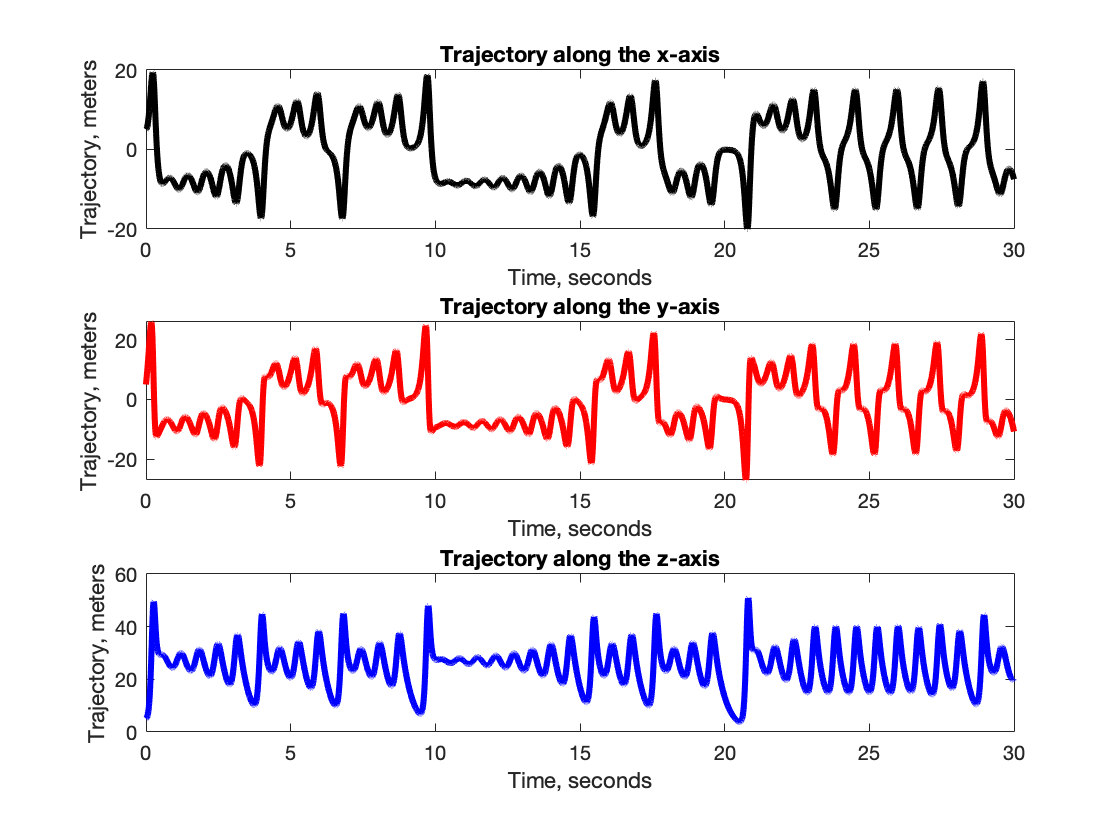

subplot(3,1,1)
plot(t,x,'k','LineWidth',3);
title('Trajectory along the x-axis');
xlabel('Time, seconds');
ylabel('Trajectory, meters');
subplot(3,1,2)
plot(t,y,'r','LineWidth',3)
title('Trajectory along the y-axis');
xlabel('Time, seconds');
ylabel('Trajectory, meters');
subplot(3,1,3)
plot(t,z,'b','LineWidth',3)
title('Trajectory along the z-axis');
xlabel('Time, seconds');
ylabel('Trajectory, meters');

For an additional 5 points, animate the position in 3D space and display the beauty of chaos.

*Note: When animating, it may not be necessary to display all points in order to decrease the playing time. You may increase the step size for time.*

figure;
hold on;
axis([-20 20 -30 30 0 55]);
k = 1;
for i = 1:length(t)
    axis manual;
    plot3(x(i),y(i),z(i),'k.','MarkerSize',10);
    view(45,45);
%     M(k) = getframe;
    pause(0.05)
    k = k + 1;
end
hold off;

## The Simple Pendulum (25 pts.)

Write down below, in Text format, the exact equation of motion for a simple pendulum. 


$$\frac{d^2 \theta }{dt^2 }=-\frac{g}{L}\sin \theta$$


Break down this second order ODE into two first order ODEs. Show your complete solution in Text format.

Let $\omega =\frac{d\theta }{\textrm{dt}}$. The second order ODE above then becomes $\frac{d\omega }{\textrm{dt}}=-\frac{g}{L}\sin \theta$. These constitute our two first order ODEs.

Write down below, in Text format, the equation of motion for a simple pendulum using the small angle approximation.


$$\frac{d^2 \theta }{dt^2 }=-\frac{g}{L}\theta$$


Break down this second order ODE into two first order ODEs. Show your complete solution in Text format.

Let $\omega =\frac{d\theta }{\textrm{dt}}$. The second order ODE above then becomes $\frac{d\omega }{\textrm{dt}}=-\frac{g}{L}\theta$. These constitute our two first order ODEs.

In order to determine the angle, $\theta$, you need to solve for the solutions to these two sets of 1st Order ODEs. Solve for the angle, $\theta$, as a function of time from $t=0$ to $t=30$$s$.

Define the step size and length of time. 

h = 0.01;       % step size
t = 0:h:30;     % time scale from 0 to 75 seconds

Choose an appropriate initial angle and angular velocity and type them down in the field below. Comment the units you are using. Write down the correct code below in order to simultaneously solve for the angle and angular velocity of the using the exact ODE.

% this code solves for the exact solution
theta1 = zeros(1,length(t));
omega1 = zeros(1,length(t));
theta1(1) = pi/4; % initial angle of pi/4 radians
omega1(1) = 0;    % initial angular velocity of 0 radians per second  
for i = 2:length(t)
    k1 = th1( theta1(i-1) );               
    k2 = th1( theta1(i-1) + 0.5*k1*h );    
    k3 = th1( theta1(i-1) + 0.5*k2*h );
    k4 = th1( theta1(i-1) + k3*h );
    omega1(i) = omega1(i-1) + (1/6)*(k1+2*k2+2*k3+k4)*h;

    k1 = omega1(i);
    k2 = omega1(i);
    k3 = omega1(i);
    k4 = omega1(i);
    theta1(i) = theta1(i-1) + (1/6)*(k1+2*k2+2*k3+k4)*h;
end

Choose an appropriate initial angle and angular velocity and type them down in the field below. Comment the units you are using. Write down the correct code below in order to simultaneously solve for the angle and angular velocity of the using the approximate ODE.

% this code solves for the exact solution
theta2 = zeros(1,length(t));
omega2 = zeros(1,length(t));
theta2(1) = pi/4; % initial angle of pi/4 radians
omega2(1) = 0;    % initial angular velocity of 0 radians per second  
for i = 2:length(t)
    k1 = th2( theta2(i-1) );               
    k2 = th2( theta2(i-1) + 0.5*k1*h );    
    k3 = th2( theta2(i-1) + 0.5*k2*h );
    k4 = th2( theta2(i-1) + k3*h );
    omega2(i) = omega2(i-1) + (1/6)*(k1+2*k2+2*k3+k4)*h;

    k1 = omega2(i);
    k2 = omega2(i);
    k3 = omega2(i);
    k4 = omega2(i);
    theta2(i) = theta2(i-1) + (1/6)*(k1+2*k2+2*k3+k4)*h;
end

Compare between the approximate and exact solutions by plot the solutions for the angles in one graph and the solutions for the angular velocities in one graph as a function of time. At which maximum angle can the approximate solution be valid? Add appropriate titles to the plot and x- and y-axes labels.

subplot(2,1,1)
plot(t,theta1,'k','LineWidth',3);
hold on
plot(t,theta2,'r','LineWidth',3)
title('Angular Velocity of the Pendulum');
xlabel('Time, seconds');
ylabel('Angular velocity, rad/s');
hold off
subplot(2,1,2)
plot(t,omega1,'k','LineWidth',3);
hold on
plot(t,omega2,'r','LineWidth',3);
title('Angle of the Pendulum');
xlabel('Time, seconds');
ylabel('Angle, radians');
hold off

For an additional 5 points, animate a swinging pendulum based on the solution of this ODE comparing between the exact and approximate solution. Display the instantaneous angle and angular velocity.

*Note: When animating, it may not be necessary to display all points in order to decrease the playing time. You may increase the step size for time.*

## The Double Pendulum (35 pts.)

A double pendulum is two pendulums connected to each other at one end, as shown in the figure.

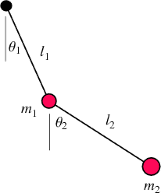

The equations of motion are given by

$\overset{\ldotp }{\dot{\theta_1 } } =\frac{6}{ml^2 }\frac{2p_{\theta_1 } -3\;\cos \left(\theta_1 -\theta_2 \right)p_{\theta_2 } }{16-9\;\cos^2 \left(\theta_1 -\theta_2 \right)}$ and $\overset{\ldotp }{\dot{\theta_2 } } =\frac{6}{ml^2 }\frac{8p_{\theta_2 } -3\;\cos \left(\theta_1 -\theta_2 \right)p_{\theta_1 } }{16-9\;\cos^2 \left(\theta_1 -\theta_2 \right)}$

Start with the following initial conditions: $\theta_1 ={90}^{\circ }$, $\theta_2 ={90}^{\circ }$, and $p_{\theta_1 } =p_{\theta_2 } =0$. To solve for the succeeding values of $p_{\theta_1 }$ and $p_{\theta_2 }$, you will need the following differential equations:

$\dot{{\dot{p} }_{\theta_1 } =-\frac{1}{2}ml^2 \left\lbrack \dot{{\dot{\theta} }_1 \dot{\theta_2 } \sin \left(\theta_1 -\theta_2 \right)+3\frac{g}{l}\sin \theta_1 } \right\rbrack }$ and $\dot{{\dot{p} }_{\theta_2 } =-\frac{1}{2}ml^2 \left\lbrack -\dot{{\dot{\theta} }_1 \dot{\theta_2 } \sin \left(\theta_1 -\theta_2 \right)+\frac{g}{l}\sin \theta_2 } \right\rbrack }$

In case of doubt with the equations, refer to the ones in the document file. 

Solve the double pendulum by solving for the angular displacements, $\theta_1$ and $\theta_2$, as a function of time from $t=0$ to $t=20$$s$.

Define the step size and length of time. 

h = 0.01;       % step size
t = 0:h:20;     % time scale from 0 to 20 seconds

Choose an appropriate initial angle and angular momentum and type them down in the field below. Comment the units you are using. Write down the correct code below in order to simultaneously solve for the angle and angular velocity of the using the exact ODE.

T1 = zeros(1,length(t));
T2 = zeros(1,length(t));
p1 = zeros(1,length(t));
p2 = zeros(1,length(t));

% initial conditions
T1(1) = 90*(pi/180);
T2(1) = 90*(pi/180);
p1(1) = 0;
p2(1) = 0;

for i = 2:length(t)
    % this code solves for theta one
    k1t1 = ft1( T1(i-1), T2(i-1), p1(i-1), p2(i-1) );
    k2t1 = ft1( T1(i-1) + 0.5*k1t1*h, T2(i-1), p1(i-1), p2(i-1) );
    k3t1 = ft1( T1(i-1) + 0.5*k2t1*h, T2(i-1), p1(i-1), p2(i-1) );
    k4t1 = ft1( T1(i-1) + k3t1*h, T2(i-1), p1(i-1), p2(i-1) );
    dT1(i) = (1/6)*(k1t1 + 2*k2t1 + 2*k3t1 + k4t1);
    T1(i) = T1(i-1) + dT1(i)*h;
    % note that dT1 is nothing but dT1/dt or theta one dot
    
    % this code solves for theta two
    k1t2 = ft2( T1(i-1), T2(i-1), p1(i-1), p2(i-1) );
    k2t2 = ft2( T1(i-1), T2(i-1) + 0.5*k1t2*h, p1(i-1), p2(i-1) ); 
    k3t2 = ft2( T1(i-1), T2(i-1) + 0.5*k2t2*h, p1(i-1), p2(i-1) );
    k4t2 = ft2( T1(i-1), T2(i-1) + k3t2*h, p1(i-1), p2(i-1) );
    dT2(i) = (1/6)*(k1t2 + 2*k2t2 + 2*k3t2 + k4t2);
    T2(i) = T2(i-1) + dT2(i)*h;
    % note that dT2 is nothing but dT2/dt or theta two dot
    
    % this code solves for p theta one
    % note the input variables dT1 and dT2, which are
    % theta one dot and theta two dot, respectively
    % one does not even need to compute for the derivative at all!
    k1p1 = fp1( T1(i-1), T2(i-1), dT1(i), dT2(i) );
    k2p1 = fp1( T1(i-1), T2(i-1), dT1(i), dT2(i) );
    k3p1 = fp1( T1(i-1), T2(i-1), dT1(i), dT2(i) );
    k4p1 = fp1( T1(i-1), T2(i-1), dT1(i), dT2(i) );
    p1(i) = p1(i-1) +  (1/6)*(k1p1 + 2*k2p1 + 2*k3p1 + k4p1)*h;
    
    % this code solves for p theta two
    k1p2 = fp2( T1(i-1), T2(i-1), dT1(i), dT2(i) );
    k2p2 = fp2( T1(i-1), T2(i-1), dT1(i), dT2(i) );
    k3p2 = fp2( T1(i-1), T2(i-1), dT1(i), dT2(i) );
    k4p2 = fp2( T1(i-1), T2(i-1), dT1(i), dT2(i) );
    p2(i) = p2(i-1) +  (1/6)*(k1p2 + 2*k2p2 + 2*k3p2 + k4p2)*h;
end

Make six subplots. You may decide how to arrange it. You must ensure that the graphs and results are clearly depicted. In the first and second subplots, plot the trajectory of the double pendulum vs time. In the third and fourth subplots, plot the momentum of the double pendulum vs time. In the fifth subplot, compare between the two phase plots of each pendulum, by plotting both $\theta_1$ vs $p_{\theta_1 }$ and $\theta_1$ vs $p_{\theta_1 }$ in one graph. In the sixth subplot, plot the trajectory of the double pendulum by plotting $\theta_1$ vs $\theta_2$ in one graph. Add appropriate titles to the plot and x- and y-axes labels.

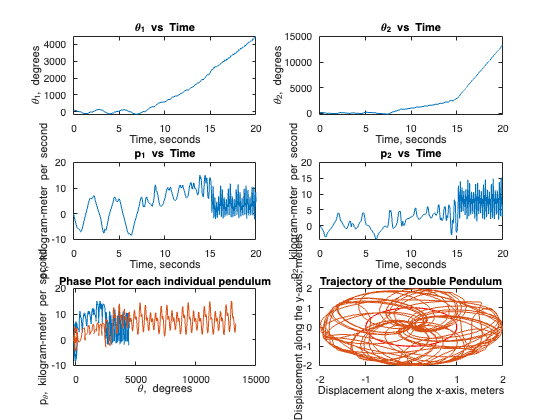

subplot(3,2,1)
plot(t,T1*180/pi);
title('\theta_1 vs Time');
xlabel('Time, seconds');
ylabel('\theta_1, degrees');
subplot(3,2,2)
plot(t,T2*180/pi)
title('\theta_2 vs Time');
xlabel('Time, seconds');
ylabel('\theta_2, degrees');
subplot(3,2,3)
plot(t,p1)
title('p_\theta_1 vs Time');
xlabel('Time, seconds');
ylabel('p_\theta_1, kilogram-meter per second');
subplot(3,2,4)
plot(t,p2)
title('p_\theta_2 vs Time');
xlabel('Time, seconds');
ylabel('p_\theta_2, kilogram-meter per second');
subplot(3,2,5)
plot(T1*180/pi,p1)
hold on;
plot(T2*180/pi,p2)
hold off;
title('Phase Plot for each individual pendulum');
xlabel('\theta, degrees');
ylabel('p_\theta, kilogram-meter per second');
subplot(3,2,6)
plot(cos(T1-pi/2),sin(T1-pi/2),'r')
hold on;
plot(cos(T1-pi/2)+cos(T2-pi/2),sin(T1-pi/2)+sin(T2-pi/2))

hold off;
title('Trajectory of the Double Pendulum');
xlabel('Displacement along the x-axis, meters');
ylabel('Displacement along the y-axis, meters');

For an additional 5 points, animate a swinging pendulum based on the solution of this ODE comparing between the exact and approximate solution. Display the instantaneous angle and angular velocity.

*Note: When animating, it may not be necessary to display all points in order to decrease the playing time. You may increase the step size for time.*

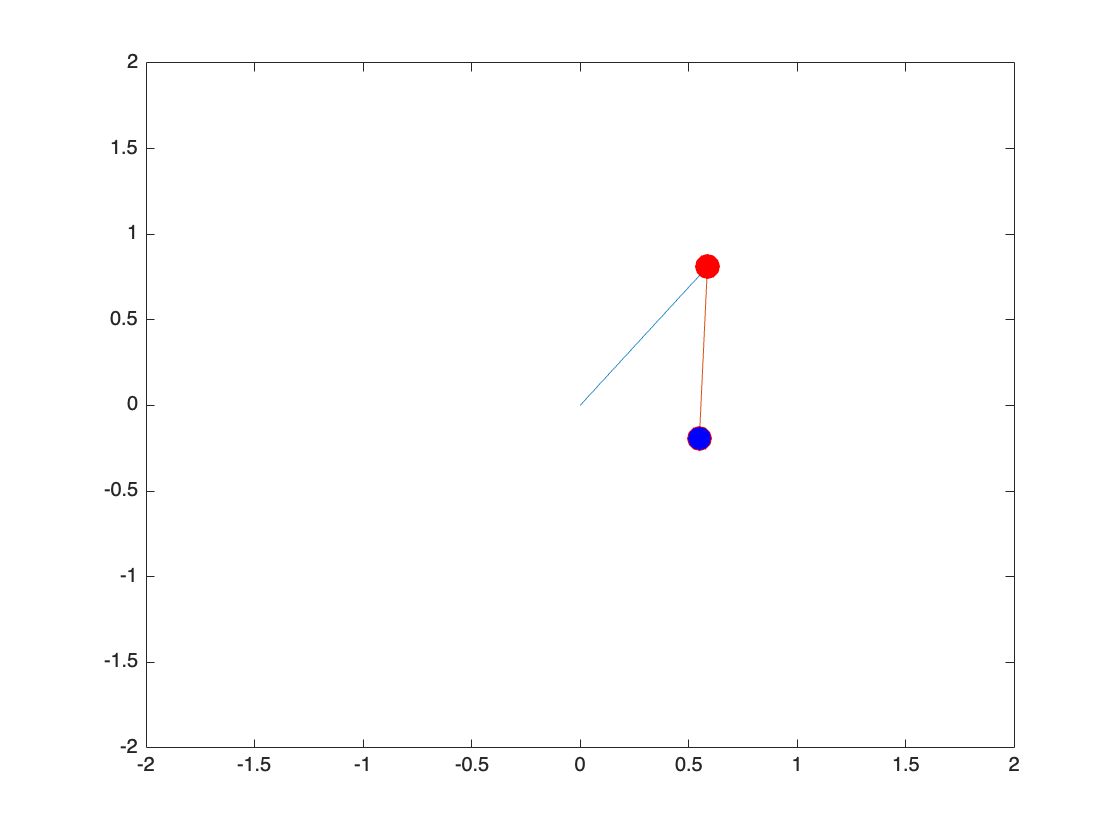

figure;
j = 1;
%x1 = [0; cos(T1(length(t))-pi/2)];
%y1 = [0; sin(T1(length(t))-pi/2)];
for i = 1:10:length(t)
%    plot(cos(T1-pi/2),sin(T1-pi/2)); 
    x1 = [0; cos(T1(i)-pi/2)];
    y1 = [0; sin(T1(i)-pi/2)];
    plot(x1,y1);
    hold on;
    x2 = [cos(T1(i)-pi/2); cos(T1(i)-pi/2)+cos(T2(i)-pi/2)];
    y2 = [sin(T1(i)-pi/2); sin(T1(i)-pi/2)+sin(T2(i)-pi/2)];
    plot(x2,y2)
    line('XData',cos(T1(i)-pi/2),'YData',sin(T1(i)-pi/2));
    k1 = plot(cos(T1(i)-pi/2),sin(T1(i)-pi/2),'ro','MarkerFaceColor','r');
    k2 = plot(cos(T1(i)-pi/2)+cos(T2(i)-pi/2),sin(T1(i)-pi/2)+sin(T2(i)-pi/2),'ro','MarkerFaceColor','b'); hold off;
    set(k1,'XData',cos(T1(i)-pi/2),'YData',sin(T1(i)-pi/2),'MarkerSize',12)
    set(k2,'XData',cos(T1(i)-pi/2)+cos(T2(i)-pi/2),'YData',sin(T1(i)-pi/2)+sin(T2(i)-pi/2),'MarkerSize',12)
    axis([-2 2 -2 2]);
%    M(j) = getframe;
    pause(0.1)
    j = j + 1;

end

function [dT1dt] = ft1( T1, T2, p1, p2 )
    m = 1; l = 1; g = 9.8;
    dT1dt = (6/(m*l^2))*(2*p1 - 3*cos(T1 - T2)*p2)/(16 - 9*(cos(T1 - T2))^2);
end

function [dT2dt] = ft2( T1, T2, p1, p2 )
    m = 1; l = 1; g = 9.8;
    dT2dt = (6/(m*l^2))*(8*p2 - 3*cos(T1 - T2)*p1)/(16 - 9*(cos(T1 - T2))^2);
end

function [dp1dt] = fp1( T1, T2, dT1, dT2 )
    m = 1; l = 1; g = 9.8;
    dp1dt = -(0.5*m*l^2)*(dT1*dT2*sin(T1 - T2) + (3*g/l)*sin(T1));
end

function [dp2dt] = fp2( T1, T2, dT1, dT2 )
    m = 1; l = 1; g = 9.8;
    dp2dt = -(0.5*m*l^2)*(-dT1*dT2*sin(T1 - T2) + (g/l)*sin(T2));
end